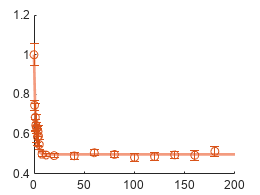

clear all
close all
colors=npg(100);

% Coherent state Ramsey fringes

main_dir='D:\Documents\MATLAB\Figures for Yb-173\CssData';

f_pop_decay_coherent=openfig([main_dir,'\p_decay.fig']);

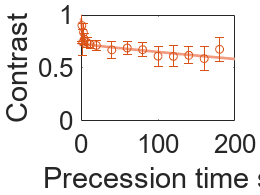

f_amp_decay_coherent=openfig([main_dir,'\c_decay.fig']);

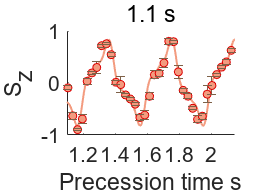



f_Ramsey_coherent_1=openfig([main_dir,'\Figure_2.fig']);

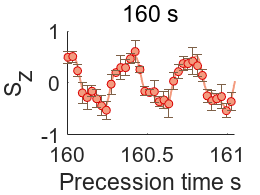

f_Ramsey_coherent_2=openfig([main_dir,'\Figure_15.fig']);

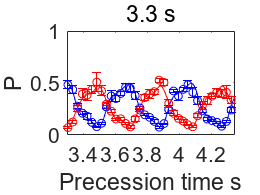

f_Ramsey_coherent_3=openfig([main_dir,'\Figure_p2_4.fig']);

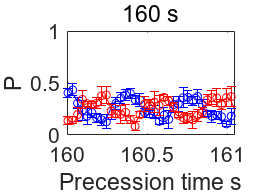

f_Ramsey_coherent_4=openfig([main_dir,'\Figure_p2_15.fig']);

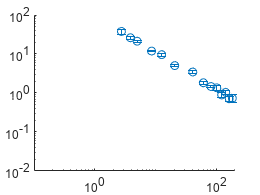



f_sensitivity_coherent=openfig([main_dir,'\SensitivityDecay.fig']);

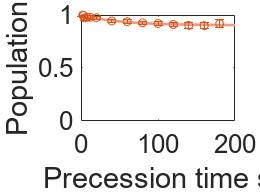


% Cat state Ramsey fringes
main_dir='D:\Documents\MATLAB\Figures for Yb-173\CatData';
f_pop_decay_cat=openfig([main_dir,'\p_decay.fig']);

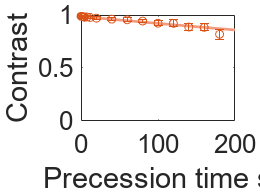

f_amp_decay_cat=openfig([main_dir,'\c_decay.fig']);

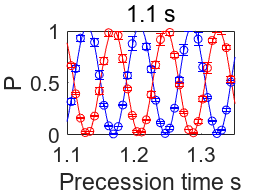


f_Ramsey_cat_1=openfig([main_dir,'\Figure_p2_15.fig']);

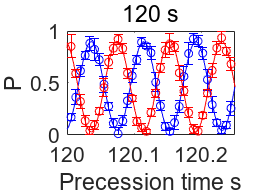

f_Ramsey_cat_2=openfig([main_dir,'\Figure_p2_4.fig']);

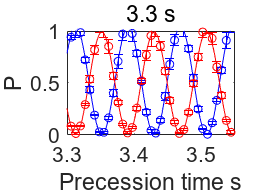

f_Ramsey_cat_3=openfig([main_dir,'\Figure_p2_13.fig']);

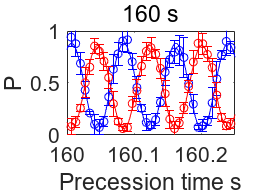

f_Ramsey_cat_4=openfig([main_dir,'\Figure_p2_2.fig']);

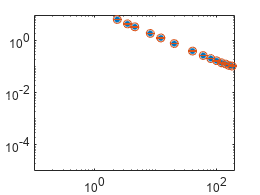


f_sensitivity_cat=openfig([main_dir,'\SensitivityDecay.fig']);


%main_dir='\\Artemis-pc\e\Data\2022-11-20\Abs-1923';



ax_1=get(f_pop_decay_cat,'CurrentAxes');
ax_2=get(f_pop_decay_coherent,'CurrentAxes');
ax_3=get(f_amp_decay_cat,'CurrentAxes');
ax_4=get(f_amp_decay_coherent,'CurrentAxes');

ax_5_1=get(f_Ramsey_cat_1,'CurrentAxes');
ax_5_2=get(f_Ramsey_cat_2,'CurrentAxes');
ax_5_3=get(f_Ramsey_cat_3,'CurrentAxes');
ax_5_4=get(f_Ramsey_cat_4,'CurrentAxes');

ax_6_1=get(f_Ramsey_coherent_1,'CurrentAxes');
ax_6_2=get(f_Ramsey_coherent_2,'CurrentAxes');
ax_6_3=get(f_Ramsey_coherent_3,'CurrentAxes');
ax_6_4=get(f_Ramsey_coherent_4,'CurrentAxes');


ax_1_C=get(ax_1,'Children');
ax_2_C=get(ax_2,'Children');
ax_3_C=get(ax_3,'Children');
ax_4_C=get(ax_4,'Children');

ax_5_C_1=get(ax_5_1,'Children');
ax_5_C_2=get(ax_5_2,'Children');
ax_5_C_3=get(ax_5_3,'Children');
ax_5_C_4=get(ax_5_4,'Children');

ax_6_C_1=get(ax_6_1,'Children');
ax_6_C_2=get(ax_6_2,'Children');
ax_6_C_3=get(ax_6_3,'Children');
ax_6_C_4=get(ax_6_4,'Children');




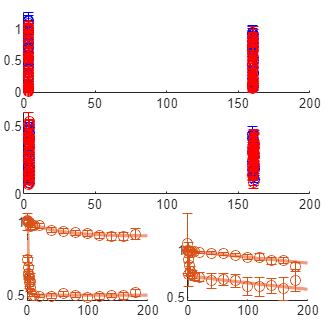

figure_3=figure;
figure_3.Color='w';
figure_3.Units='inches';
figure_3.Position=[1 0 12 12];

t = tiledlayout(3,2,'TileSpacing','compact','Padding','compact');

ax1=nexttile(5,[1 1]);
ax2=nexttile(6,[1 1]);

% ax5_3=nexttile(1);
% ax5_4=nexttile(2);
%
% ax6_3=nexttile(3);
% ax6_4=nexttile(4);

% ax5_3=nexttile(1,[1,2]);
% ax5_4=ax5_3;
%
% ax6_3=nexttile(3,[1,2]);
% ax6_4=ax6_3;

ax_top=axes('Position',[0.0723    0.7149    0.8802    0.2476]);
ax5_3=ax_top;
ax5_4=ax_top;

ax_middle=axes('Position',[0.0723    0.4054    0.8802    0.2476]);
ax6_3=ax_middle;
ax6_4=ax_middle;

handle_1_coherent=copyobj(ax_2_C, ax1);
handle_2_coherent=copyobj(ax_4_C, ax2);
handle_1_cat=copyobj(ax_1_C, ax1);
handle_2_cat=copyobj(ax_3_C, ax2);


%handle_5_cat_1=copyobj(ax_5_C_1, ax5_1);
%handle_5_cat_2=copyobj(ax_5_C_2, ax5_2);
handle_5_cat_3=copyobj(ax_5_C_3, ax5_3);
handle_5_cat_4=copyobj(ax_5_C_4, ax5_4);

%handle_6_coherent_1=copyobj(ax_6_C_1, ax6_1);
%handle_6_coherent_2=copyobj(ax_6_C_2, ax6_2);
handle_6_coherent_3=copyobj(ax_6_C_3, ax6_3);
handle_6_coherent_4=copyobj(ax_6_C_4, ax6_4);

%% Get handle
subfig_a_errorbar_cat=handle_1_cat(1);
subfig_a_line_cat=handle_1_cat(2);
subfig_b_errorbar_cat=handle_2_cat(1);
subfig_b_line_cat=handle_2_cat(2);

subfig_a_errorbar_coherent=handle_1_coherent(1);
subfig_a_line_coherent=handle_1_coherent(2);
subfig_b_errorbar_coherent=handle_2_coherent(1);
subfig_b_line_coherent=handle_2_coherent(2);

subfig_3_line_cat_1=handle_5_cat_3(3);
subfig_3_line_cat_2=handle_5_cat_3(4);
subfig_3_errorbar_cat_1=handle_5_cat_3(1);
subfig_3_errorbar_cat_2=handle_5_cat_3(2);

subfig_4_line_cat_1=handle_5_cat_4(3);
subfig_4_line_cat_2=handle_5_cat_4(4);
subfig_4_errorbar_cat_1=handle_5_cat_4(1);
subfig_4_errorbar_cat_2=handle_5_cat_4(2);


subfig_3_line_css_1=handle_6_coherent_3(3);
subfig_3_line_css_2=handle_6_coherent_3(4);
subfig_3_errorbar_css_1=handle_6_coherent_3(1);
subfig_3_errorbar_css_2=handle_6_coherent_3(2);

subfig_4_line_css_1=handle_6_coherent_4(3);
subfig_4_line_css_2=handle_6_coherent_4(4);
subfig_4_errorbar_css_1=handle_6_coherent_4(1);
subfig_4_errorbar_css_2=handle_6_coherent_4(2);




## Line style

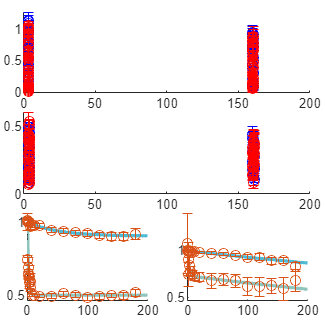


%Linewidth

subfig_a_line_cat.LineWidth=2;
subfig_a_line_coherent.LineWidth=2;

subfig_b_line_cat.LineWidth=2;
subfig_b_line_coherent.LineWidth=2;

subfig_3_line_css_1.LineWidth=1.5;
subfig_3_line_css_2.LineWidth=1.5;
subfig_4_line_css_1.LineWidth=1.5;
subfig_4_line_css_2.LineWidth=1.5;

subfig_3_line_cat_1.LineWidth=1.5;
subfig_3_line_cat_2.LineWidth=1.5;
subfig_4_line_cat_1.LineWidth=1.5;
subfig_4_line_cat_2.LineWidth=1.5;

% Line color
subfig_a_line_cat.Color=colors(12,:);
subfig_a_line_coherent.Color=colors(65,:);

subfig_b_line_cat.Color=colors(12,:);
subfig_b_line_coherent.Color=colors(65,:);

subfig_3_line_cat_1.Color=colors(3,:);
subfig_3_line_cat_2.Color=colors(71,:);
subfig_4_line_cat_1.Color=colors(3,:);
subfig_4_line_cat_2.Color=colors(71,:);

subfig_3_line_css_1.Color=colors(3,:);
subfig_3_line_css_2.Color=colors(71,:);
subfig_4_line_css_1.Color=colors(3,:);
subfig_4_line_css_2.Color=colors(71,:);

## Errorbar style

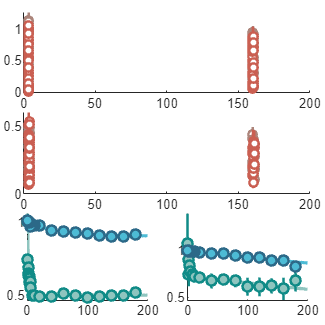

% errorbar linewidth
subfig_a_errorbar_cat.LineWidth=1.5;
subfig_a_errorbar_coherent.LineWidth=1.5;
subfig_b_errorbar_cat.LineWidth=1.5;
subfig_b_errorbar_coherent.LineWidth=1.5;

subfig_3_errorbar_cat_1.LineWidth=1.5;
subfig_3_errorbar_cat_2.LineWidth=1.5;
subfig_4_errorbar_cat_1.LineWidth=1.5;
subfig_4_errorbar_cat_2.LineWidth=1.5;

subfig_3_errorbar_css_1.LineWidth=1.5;
subfig_3_errorbar_css_2.LineWidth=1.5;
subfig_4_errorbar_css_1.LineWidth=1.5;
subfig_4_errorbar_css_2.LineWidth=1.5;

% errorbar color

subfig_a_errorbar_cat.Color=colors(31,:);
subfig_a_errorbar_coherent.Color=colors(26,:);
subfig_b_errorbar_cat.Color=colors(31,:);
subfig_b_errorbar_coherent.Color=colors(26,:);


subfig_3_errorbar_cat_1.Color=colors(3,:);
subfig_3_errorbar_cat_2.Color=colors(71,:);
subfig_4_errorbar_cat_1.Color=colors(3,:);
subfig_4_errorbar_cat_2.Color=colors(71,:);

subfig_3_errorbar_css_1.Color=colors(3,:);
subfig_3_errorbar_css_2.Color=colors(71,:);
subfig_4_errorbar_css_1.Color=colors(3,:);
subfig_4_errorbar_css_2.Color=colors(71,:);

% errorbar markersize
subfig_a_errorbar_cat.MarkerSize=6;
subfig_a_errorbar_coherent.MarkerSize=6;
subfig_b_errorbar_cat.MarkerSize=6;
subfig_b_errorbar_coherent.MarkerSize=6;

subfig_3_errorbar_cat_1.MarkerSize=5;
subfig_3_errorbar_cat_2.MarkerSize=5;
subfig_4_errorbar_cat_1.MarkerSize=5;
subfig_4_errorbar_cat_2.MarkerSize=5;

subfig_3_errorbar_css_1.MarkerSize=5;
subfig_3_errorbar_css_2.MarkerSize=5;
subfig_4_errorbar_css_1.MarkerSize=5;
subfig_4_errorbar_css_2.MarkerSize=5;

% errorbar capsize

subfig_a_errorbar_cat.CapSize=0;
subfig_a_errorbar_coherent.CapSize=0;
subfig_b_errorbar_cat.CapSize=0;
subfig_b_errorbar_coherent.CapSize=0;

subfig_3_errorbar_cat_1.CapSize=0;
subfig_3_errorbar_cat_2.CapSize=0;
subfig_4_errorbar_cat_1.CapSize=0;
subfig_4_errorbar_cat_2.CapSize=0;

subfig_3_errorbar_css_1.CapSize=0;
subfig_3_errorbar_css_2.CapSize=0;
subfig_4_errorbar_css_1.CapSize=0;
subfig_4_errorbar_css_2.CapSize=0;

% errorbar markeredge color

% errorbar MarkerEdgeColor
subfig_a_errorbar_cat.MarkerEdgeColor=colors(31,:);
subfig_a_errorbar_coherent.MarkerEdgeColor=colors(26,:);
subfig_b_errorbar_cat.MarkerEdgeColor=colors(31,:);
subfig_b_errorbar_coherent.MarkerEdgeColor=colors(26,:);

subfig_3_errorbar_cat_1.MarkerEdgeColor=colors(3,:);
subfig_3_errorbar_cat_2.MarkerEdgeColor=colors(71,:);
subfig_4_errorbar_cat_1.MarkerEdgeColor=colors(3,:);
subfig_4_errorbar_cat_2.MarkerEdgeColor=colors(71,:);

subfig_3_errorbar_css_1.MarkerEdgeColor=colors(3,:);
subfig_3_errorbar_css_2.MarkerEdgeColor=colors(71,:);
subfig_4_errorbar_css_1.MarkerEdgeColor=colors(3,:);
subfig_4_errorbar_css_2.MarkerEdgeColor=colors(71,:);

% errorbar markerfacecolor

subfig_a_errorbar_cat.MarkerFaceColor=colors(12,:);
subfig_a_errorbar_coherent.MarkerFaceColor=colors(65,:);
subfig_b_errorbar_cat.MarkerFaceColor=colors(12,:);
subfig_b_errorbar_coherent.MarkerFaceColor=colors(65,:);

subfig_3_errorbar_cat_1.MarkerFaceColor=[1 1 1];
subfig_3_errorbar_cat_2.MarkerFaceColor=[1 1 1];
subfig_4_errorbar_cat_1.MarkerFaceColor=[1 1 1];
subfig_4_errorbar_cat_2.MarkerFaceColor=[1 1 1];

subfig_3_errorbar_css_1.MarkerFaceColor=[1 1 1];
subfig_3_errorbar_css_2.MarkerFaceColor=[1 1 1];
subfig_4_errorbar_css_1.MarkerFaceColor=[1 1 1];
subfig_4_errorbar_css_2.MarkerFaceColor=[1 1 1];

## axes setup

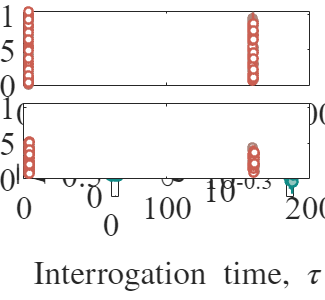

% box on
ax1.Box='on';
ax2.Box='on';

ax5_3.Box='on';
ax5_4.Box='on';

ax6_3.Box='on';
ax6_4.Box='on';

%
% axis limits & scales
ax1.XLim=[-1 200];
ax2.XLim=[-1 200];
% ax5_3.XLim=[3.25 3.95];
% ax5_4.XLim=[159.95 160.65];
% ax6_3.XLim=[3.25 3.95];
% ax6_4.XLim=[159.95 160.65];

ax1.YLim=[0 1.05];ax1.YScale="linear";
ax2.YScale="log";
ax2.YTick=[10^-0.3 10^-0.2 10^-0.1 10^0];
ax2.YTickLabel={'10^{-0.3}','10^{-0.2}','10^{-0.1}','10^{0}'};
ax2.YLim=[0.45 1.05];



ax5_3.YLim=[0 1.05];
ax5_4.YLim=[0 1.05];
ax6_3.YLim=[0 1.05];
ax6_4.YLim=[0 1.05];

% axis fontsize
ax1.FontSize=20;
ax2.FontSize=20;
ax5_3.FontSize=20;
ax5_4.FontSize=20;
ax6_3.FontSize=20;
ax6_4.FontSize=20;

% axis fontname
ax1.FontName='Times New Roman';
ax2.FontName='Times New Roman';
ax5_3.FontName='Times New Roman';
ax5_4.FontName='Times New Roman';
ax6_3.FontName='Times New Roman';
ax6_4.FontName='Times New Roman';

% xlabel
xlabel(t,'$\mathrm{Interrogation\ time,}\ \tau\ \mathrm{(s)}$','Interpreter','latex','FontSize', 20,'FontName','Times New Roman')

% ylabel
ylabel(ax1,'$\overline{P}$','Interpreter','latex','FontSize', 20,'FontName','Times New Roman')
ylabel(ax2,'$\mathcal{C}$','Interpreter','latex','FontSize', 20,'FontName','Times New Roman')

ylabel(ax5_3,'$P$','Interpreter','latex','FontSize', 20,'FontName','Times New Roman')
%ylabel(ax5_4,'$P$','Interpreter','latex','FontSize', 20,'FontName','Times New Roman')
ylabel(ax6_3,'$P$','Interpreter','latex','FontSize', 20,'FontName','Times New Roman')

%ylabel(ax6_4,'$P$','Interpreter','latex','FontSize', 20,'FontName','Times New Roman')

%ax5_4.YAxis.Visible='off';
%ax6_4.YAxis.Visible='off'
%ax5_4.YTick=[];
%ax6_4.YTick=[];


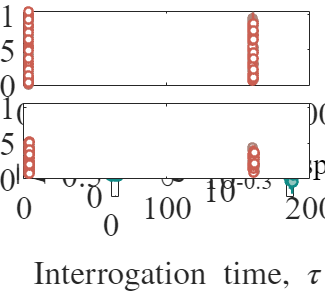

%legend(ax1,[subfig_a_errorbar_cat,subfig_a_errorbar_coherent],{'Cat state','Coherent state'},'Box','off','Location','southeast')
%legend(ax6_4,[subfig_3_errorbar_cat_1,subfig_3_errorbar_cat_2],{'$P_{+5/2}$','$P_{-5/2}$'},'Box','off','Location','northeast','Interpreter','latex','FontSize', 20,'FontName','Times New Roman')


legend(ax1,[subfig_a_errorbar_cat,subfig_a_errorbar_coherent],{'Cat state','Coherent spin state'},'Box','off','Location','southwest')



% xlabel(ax5,'Interrogation time s')
% xlabel(ax6,'Interrogation time s')
%
% xlabel(ax1,'$\mathrm{Interrogation\ time,}\ \tau\ \mathrm{(s)}$','Interpreter','latex')
% xlabel(ax2,'$\mathrm{Interrogation\ time,}\ \tau\ \mathrm{(s)}$','Interpreter','latex')
% xlabel(ax5,'$\tau\ \mathrm{(s)}$','Interpreter','latex')
% xlabel(ax6,'$\tau\ \mathrm{(s)}$','Interpreter','latex')
%
%
% ylabel(ax1,'Population')
% ylabel(ax2,'Contrast')
% ylabel(ax5,'Parity')
% ylabel(ax6,'Parity')
%
% % axis fonts
% ax1.FontSize=14;
% ax2.FontSize=14;
% ax5.FontSize=14;
% ax6.FontSize=14;
%
% ax1.FontName='Times New Roman';
% ax2.FontName='Times New Roman';
% ax5.FontName='Times New Roman';
% ax6.FontName='Times New Roman';
%
% ax1.Box='on';
% ax2.Box='on';
% ax5.Box='on';
% ax6.Box='on';
%
% legend([subfig_a_errorbar_cat,subfig_a_errorbar_coherent],{'Cat state','Coherent state'},'Box','off','Location','southeast')
% legend([subfig_b_errorbar_cat,subfig_b_errorbar_coherent],{'Cat state','Coherent state'},'Box','off','Location','southeast')
% %legend([subfig_c_errorbar_cat],{'Cat state'},'Box','off','Location','northeast')
% %legend([subfig_d_errorbar_coherent],{'Coherent state'},'Box','off','Location','northeast')



ax_top.XLim=[3.25 160.55];
ax_middle.XLim=[3.25 160.55];
h_top=breakxaxis(ax_top,[3.85 159.95],0.04);

annotationAxes =   Axes - 属性:

             XLim: [3.2500 160.5500]
             YLim: [0 1.0500]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.0723 0.7149 0.8802 0.2476]
            Units: 'normalized'

  显示 所有属性


h_middle=breakxaxis(ax_middle,[3.85 159.95],0.04);

annotationAxes =   Axes - 属性:

             XLim: [3.2500 160.5500]
             YLim: [0 1.0500]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.0723 0.4054 0.8802 0.2476]
            Units: 'normalized'

  显示 所有属性



l1=legend(h_middle.leftAxes,[subfig_3_errorbar_cat_1,subfig_3_errorbar_cat_2],{'$P_{+5/2}$','$P_{-5/2}$'},'Box','off','Location','northwest','Interpreter','latex','FontSize', 20,'FontName','Times New Roman','TextColor',[1 1 1])

l1 =   Legend ($P_{+5/2}$, $P_{-5/2}$) - 属性:

         String: {'$P_{+5/2}$'  '$P_{-5/2}$'}
       Location: 'northwest'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.0813 0.5785 0.0972 0.0646]
          Units: 'normalized'

  显示 所有属性


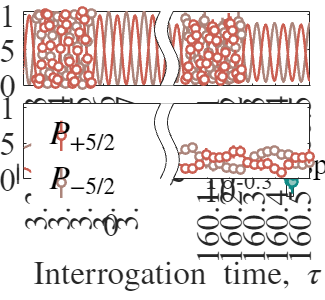

annotation(figure_3,'textbox',...
    [0.116451388888888 0.5707532168567 0.0808980377185433 0.069405828868944],...
    'String',{'$P_{+5/2}$','$P_{-5/2}$'},...
    'Interpreter','latex',...
    'FontSize',20,...
    'FontName','Times New Roman',...
    'EdgeColor','none');



% ax5_3.XLim=[3.25 3.95];
% ax5_4.XLim=[159.95 160.65];
% ax6_3.XLim=[3.25 3.95];
% ax6_4.XLim=[159.95 160.65];

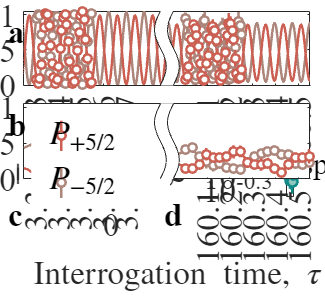

annotation(figure_3,'textbox',...
    [0.0 0.93 0.05 0.05],...
    'String','a',...
    'FontWeight','bold',...
    'FontSize',20,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');

annotation(figure_3,'textbox',...
    [0.0 0.62 0.05 0.05],...
    'String','b',...
    'FontWeight','bold',...
    'FontSize',20,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');

annotation(figure_3,'textbox',...
    [0.0 0.32 0.05 0.05],...
    'String','c',...
    'FontWeight','bold',...
    'FontSize',20,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');

annotation(figure_3,'textbox',...
    [0.48 0.32 0.05 0.05],...
    'String','d',...
    'FontWeight','bold',...
    'FontSize',20,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');

print(figure_3, ['\\Artemis-pc\e\Data\DataForPub','\Figure3.png'],'-r600','-dpng');
hgexport(figure_3, ['\\Artemis-pc\e\Data\DataForPub','\Figure3.eps'])